# Experiment with Focus Stacking

Experiment with focus stacking using our cp (Computational Photography) classes. Eventually add object and camera motion.

## Create a pbrt scene we can use

Using pbrt lets us get the highest-fidelity rendering. We use its lens model to get realistic depth and occlusion rendering.

ieInit();
sceneLuminance = 1000;
numRays = 128;
filmResolution = 1024;

sceneChoice = "CornellBoxReference";

% for legacy reasons, scenes don't have a uniform naming scheme,
% so we map the user's choice to the appropriate options
if strcmp(sceneChoice, "Cornell Box with Bunny")
    scenePath = 'Cornell_BoxBunnyChart';        
    sceneName = 'cornell box bunny chart';
elseif strcmp(sceneChoice, "CornellBoxReference")
    scenePath = "cornell_box";
    sceneName = "cornell_box";
else
    scenePath = 'ChessSet';
    sceneName = 'chessSet';
end

pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance); %, ...
    %'lensFile','dgauss.22deg.3.0mm.json');

Read 7 materials.
Read 0 textures.
***Scene parsed.


pinholeCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, ...
    'sceneLuminance', sceneLuminance);

Read 7 materials.
Read 0 textures.
***Scene parsed.


% match to sensor size, should be a formula
pinholeCPScene.thisR.set('fov', 30);

% room light might be throwing off AE
%pbrtCPScene.thisR.set('skymap','room.exr','rotation val',[90, -90, 0]);
lightName = 'from camera';
ourLight = piLightCreate(lightName,...
                        'type','distant',...
                        'cameracoordinate', true);
pbrtCPScene.thisR.set('lights', ourLight,'add');
pinholeCPScene.thisR.set('lights', ourLight, 'add');

%pinholeCPScene.thisR.set('focaldistance', '.005');

if strcmp(sceneName, "cornell_box")
    bunny = piAssetLoad('bunny.mat');
    bunny.name = 'Bunny';
    pbrtCPScene.thisR = piRecipeMerge(pbrtCPScene.thisR, bunny.thisR);
    pbrtCPScene.thisR.set('asset', 'Bunny_B', 'world position',...
        [0 0 1.3]);    % in case bunny is out of our frame
    
    %if you want object motion
    pbrtCPScene.objectMotion = {{'Bunny_B', [0 .01 0], []}};

    % now calculate the distance of the bunny
    bPos = pbrtCPScene.thisR.recipeGet('asset', 'Bunny_B', 'world position');
    cPos = pbrtCPScene.thisR.lookAt.from;
    
    bDistance = sum((bPos-cPos).^2)^.5;
    
    %mcc = piAssetLoad('macbeth.mat');
    %pbrtCPScene.thisR = piRecipeMerge(pbrtCPScene.thisR, mcc.thisR);
    %pbrtCPScene.thisR.set('material', 'add', mcc.thisR.matList{1});
    %pbrtCPScene.thisR.set('asset', mcc_id, 'world position', [0, 1, 1]);
    
    bar = load('slantedbar.mat');
    %[~, bar_id] = pbrtCPScene.thisR.set('asset',1, 'add', bar.assetTree.Node{1});
    %pbrtCPScene.thisR.set('material', 'add', bar.matList{1});

    coord = load('coordinate.mat');
    pbrtCPScene.thisR = piRecipeMerge(pbrtCPScene.thisR, coord.thisR);
else
    bDistance = 1;
end

## Create our sample camera

Just one module with a pre-made sensor and default optics.

% some timing code, just to see how fast we run...
setpref('ISET', 'benchmarkstart', cputime); 
setpref('ISET', 'tStart', tic);

% We'll use a pre-defined sensor for our Camera Module, and let it use
% default optics for now. We can then assign the module to our camera:
ourSensor = sensorCreate('imx363'); 
ourSensor = sensorSet(ourSensor, 'size', [1024, 1280]);
pinholeSensor = sensorCreate('imx363'); 
pinholeSensor = sensorSet(pinholeSensor, 'size', [1024, 1280]);

% cpBurstCamera is a sub-class of cpCamera that implements simple HDR and Burst
% capture and processing
ourCamera = cpBurstCamera(); 
% Cameras can eventually have more than one module (lens + sensor)
% but for now, we just create one using our sensor
ourCamera.cmodules(1) = cpCModule('sensor', ourSensor); 

% try to make the pinhole a pinhole:)
% if it works, should integrate into cpCamera
pinholeCamera = cpBurstCamera();
pinholeCamera.cmodules(1) = cpCModule('sensor', pinholeSensor);
pinholeCamera.cmodules(1).oi.optics = opticsSet(pinholeCamera.cmodules(1).oi.optics,'fnumber',8);

## Let's Look at the Camera we've Created

cpCameraWindow is actually a mini-application, that lets you see the properties of your camera, and the scene you've chosen. You can use it to take photos in whatever modes your camera supports. It also allows to to set Advanced Processing, which tells cameras that support it to do additional processing like image registration and tonemapping, as needed, in their ISP, instead of the default combination of frames in the sensor.

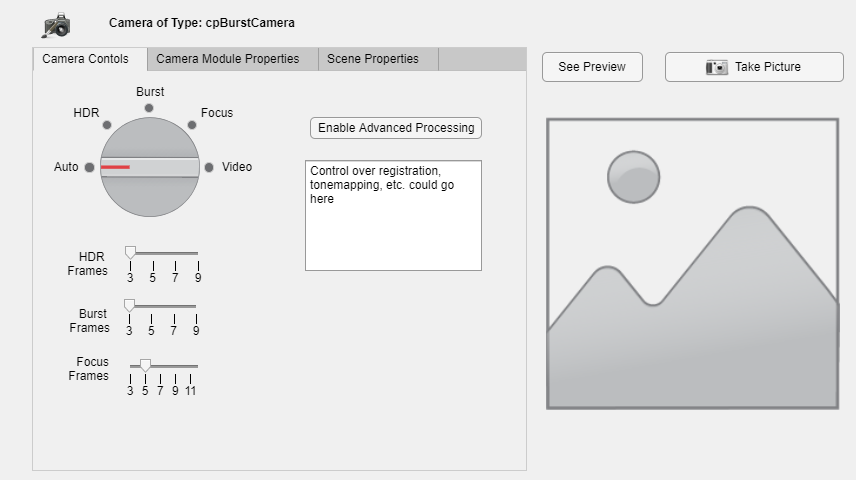

cpCameraWindow(ourCamera, pbrtCPScene);

## Take Pictures

Using single-image Auto, multi-image Burst and Focus Stacked.

Elapsed time is 1.065917 seconds.
Started Docker with 0: docker  --context render-vista run -d -it  --gpus device=0  --name pbrt-gpu-Windows19097  -v /home/david/iset/iset3d-v4/local/:/iset/iset3d-v4/local/  digitalprodev/pbrt-v4-gpu-ampere-mux-shared:latest bash
 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/cornell_box/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/cornell_box/
Pushed scene to remote in:   0.97
Render: docker --context render-vista exec -i  pbrt-gpu-Windows19097 sh -c "cd /iset/iset3d-v4/local/cornell_box && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/cornell_box.exr cornell_box.pbrt"
Successfuly rendered remotely in:  44.38
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/cornell_box/renderings/ /mnt/c/iset/iset3d-v4/local/cornell_box/renderings
Retrieved output in:   0.75
Complete render took: 4.94e+01 seconds.*** Rendering time for cornell_box:  49.4 sec ***

exr2bin done.exr2bin do

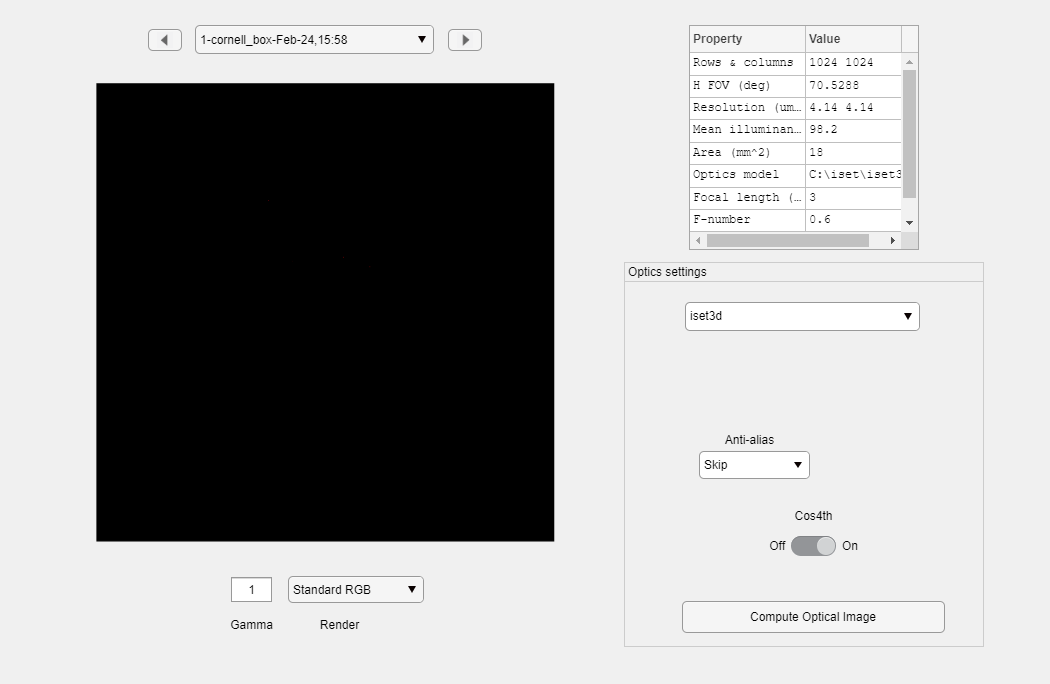

 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/cornell_box/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/cornell_box/
Pushed scene to remote in:   0.97
Render: docker --context render-vista exec -i  pbrt-gpu-Windows19097 sh -c "cd /iset/iset3d-v4/local/cornell_box && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/cornell_box.exr cornell_box.pbrt"
Successfuly rendered remotely in:  34.95
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/cornell_box/renderings/ /mnt/c/iset/iset3d-v4/local/cornell_box/renderings
Retrieved output in:   1.08
Complete render took: 3.80e+01 seconds.*** Rendering time for cornell_box:  38.0 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Elapsed time is 1.154964 seconds.
 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/cornell_box/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/cornell_box/
Pushed scene to remote in:   0.85
Render: docker --conte

Status:
     1

Result:
pbrt version 4 (built Feb 21 2022 at 21:02:59)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.
Error: Coefficient must be positive. It looks focusDistance 0.010796  is too short for a given lenses configuration

*** Rendering time for cornell_box:  4.3 sec ***



Error using piEXR2ISET (line 57)
The value of 'inputFile' is invalid. It must satisfy the function: @(x)(exist(x,'file')).

Error in piRender (line 266)
    ieObject = piEXR2ISET(outFile, 'recipe',thisR,'label',thisR.metadata.rendertype);

Error in cpScene/render (

% baseline test
autoCamera = cpCamera();
autoImage = autoCamera.TakePicture(pbrtCPScene, 'Auto',...
    'imageName','Auto Mode',...
    'focusMode', 'Manual', 'focusParam', bDistance* 1.1);

imshow(autoImage);

burstImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst',...
    'focusMode', 'Manual', 'focusParam', bDistance* 1.1, 'insensorIP',false);

stackedImage = ourCamera.TakePicture(pbrtCPScene, 'FocusStack', ...
    'focusMode', 'Stack', 'focusParam', 9, ...
    'imageName','Focus Stacked',...
    'insensorIP',false);

pinholeImage = pinholeCamera.TakePicture(pinholeCPScene, 'Auto',...
    'insensorIP', false);

cpCompareImages(burstImage, stackedImage, 'Burst vs. Stacked with no motion');
cpCompareImages(pinholeImage, stackedImage, 'Pinhole vs. Stacked with no motion');
cpCompareImages(pinholeImage, burstImage, 'Pinhole vs. Burst with no motion');

## Print out some timing stats

Just for human consumption

tTotal = toc(getpref('ISET','tStart'));
afterTime = cputime;
beforeTime = getpref('ISET', 'benchmarkstart', 0);
glData = opengl('data');
disp(strcat("cpCompare ran  on: ", glData.Vendor, " ", glData.Renderer, "with driver version: ", glData.Version)); 
disp(strcat("cpCompare ran  in: ", string(afterTime - beforeTime), " seconds of CPU time."));
disp(strcat("cpCompare ran  in: ", string(tTotal), " total seconds."));